clear;
clc;

% En primer lugar, se cargan los datos y se crean las variables A y B como
% los vectores de concentraciones de cada muestra en mg/kg
x=load('SMwr_Ex_01.txt');
A = x(:,2);
B = x(:,3);

% Punto 1.
% Histogramas de A
H1A = histogram(A,'BinWidth',1)

H1A =   Histogram with properties:

             Data: [20×1 double]
           Values: [6 3 4 1 0 1 1 2 1 0 1]
          NumBins: 11
         BinEdges: [0 1 2 3 4 5 6 7 8 9 10 11]
         BinWidth: 1
        BinLimits: [0 11]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


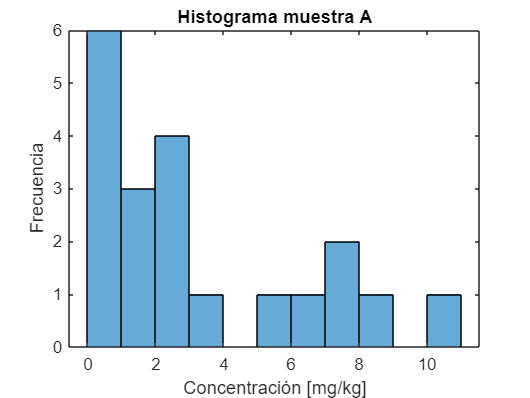

hold on
title('Histograma muestra A')
xlabel('Concentración [mg/kg]')
ylabel('Frecuencia')
hold off


H2A = histogram(A,'BinWidth',2)

H2A =   Histogram with properties:

             Data: [20×1 double]
           Values: [9 5 1 3 1 1]
          NumBins: 6
         BinEdges: [0 2 4 6 8 10 12]
         BinWidth: 2
        BinLimits: [0 12]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


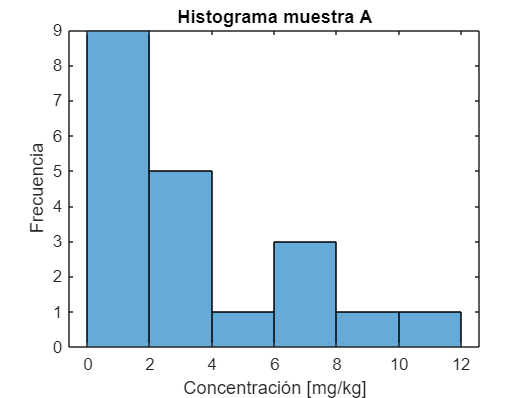

hold on
title('Histograma muestra A')
xlabel('Concentración [mg/kg]')
ylabel('Frecuencia')
hold off


H3A = histogram(A,'BinWidth',5)

H3A =   Histogram with properties:

             Data: [20×1 double]
           Values: [14 5 1]
          NumBins: 3
         BinEdges: [0 5 10 15]
         BinWidth: 5
        BinLimits: [0 15]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


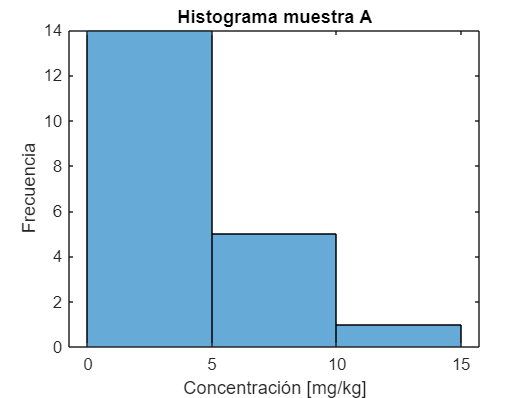

hold on
title('Histograma muestra A')
xlabel('Concentración [mg/kg]')
ylabel('Frecuencia')
hold off

% Hay 5 datos que tienen valores entre 5 y 10, de acuerdo con los
% histogramas.

% Punto 2
% Histogramas de B
H1B = histogram(B,'BinWidth',1)

H1B =   Histogram with properties:

             Data: [20×1 double]
           Values: [4 2 4 1 1 3 0 0 0 0 0 1 1 0 0 1 0 1 0 1]
          NumBins: 20
         BinEdges: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20]
         BinWidth: 1
        BinLimits: [0 20]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


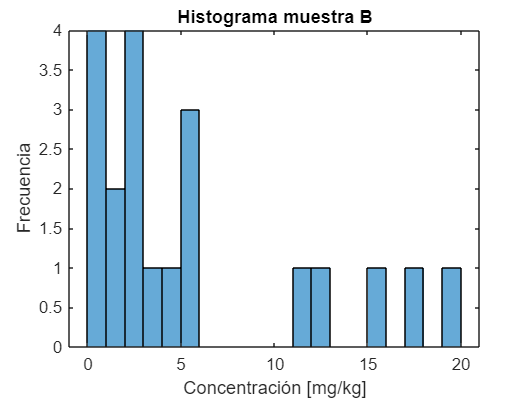

hold on
title('Histograma muestra B')
xlabel('Concentración [mg/kg]')
ylabel('Frecuencia')
hold off


H2B = histogram(B,'BinWidth',2)

H2B =   Histogram with properties:

             Data: [20×1 double]
           Values: [6 5 4 0 0 1 1 1 1 1]
          NumBins: 10
         BinEdges: [0 2 4 6 8 10 12 14 16 18 20]
         BinWidth: 2
        BinLimits: [0 20]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


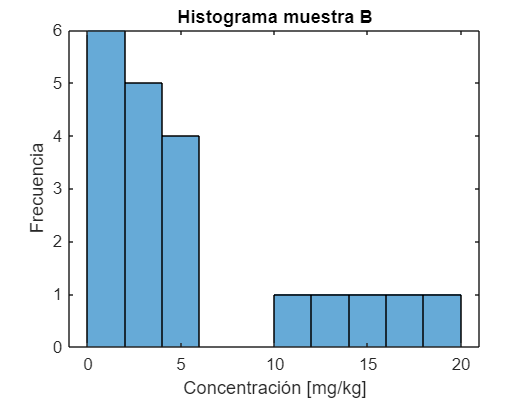

hold on
title('Histograma muestra B')
xlabel('Concentración [mg/kg]')
ylabel('Frecuencia')
hold off


H3B = histogram(B,'BinWidth',5)

H3B =   Histogram with properties:

             Data: [20×1 double]
           Values: [12 3 2 3]
          NumBins: 4
         BinEdges: [0 5 10 15 20]
         BinWidth: 5
        BinLimits: [0 20]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


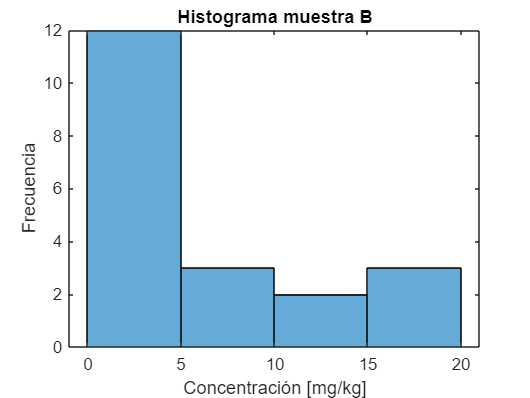

hold on
title('Histograma muestra B')
xlabel('Concentración [mg/kg]')
ylabel('Frecuencia')
hold off


% Hay 2 datos que tienen valores entre 5 y 10, de acuerdo con los
% histogramas.

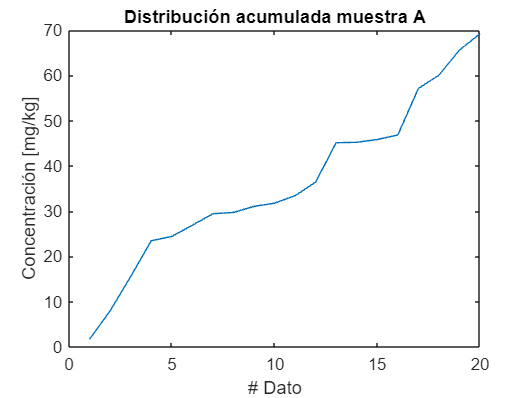

% Punto 3

% Distribución acumulativa Muestra A
S_A = zeros(1,length(A));

for i = 1:length(A)
    S_A(i) = sum(A(1:i));
end
A;
S_A;
plot(1:length(A), S_A)
hold on
title('Distribución acumulada muestra A')
ylabel('Concentración [mg/kg]')
xlabel('# Dato')
hold off

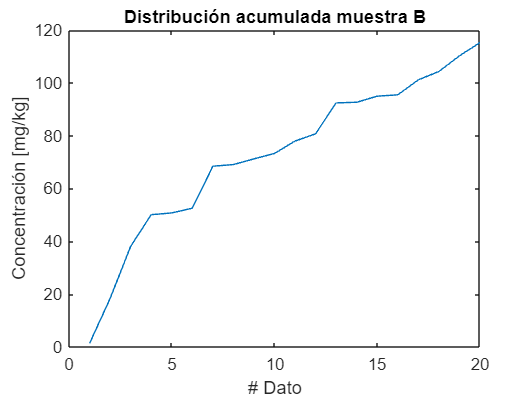



% Distribución acumulativa Muestra B
S_B = zeros(1,length(B));

for i = 1:length(B)
    S_B(i) = sum(B(1:i));
end
B;
S_B;
plot(1:length(B), S_B)
hold on
title('Distribución acumulada muestra B')
ylabel('Concentración [mg/kg]')
xlabel('# Dato')
hold off

% Punto 4.
% Momentos estadísticos
A_1 = sort(A);
B_1 = sort(B);

% Muestra A
A_m = mean(A)

A_m = 3.4595

A_var = var(A)

A_var = 9.7573

A_skew = skewness(A)

A_skew = 0.8536

A_cur = kurtosis(A)

A_cur = 2.4101

% Cuantiles
A_Q1 = A_1(round(length(A_1)/4,0))

A_Q1 = 0.9600

A_Q3 = A_1(round(3*length(A_1)/4,0))

A_Q3 = 5.5400

A_med = median(A_1)

A_med = 2.5100

A_int = A_Q3 - A_Q1

A_int = 4.5800


% Muestra B
B_m = mean(B)

B_m = 5.7635

B_var = var(B)

B_var = 36.9446

B_skew = skewness(B)

B_skew = 1.1392

B_cur = kurtosis(B)

B_cur = 2.9198

% Cuantiles
B_Q1 = B_1(round(length(B_1)/4,0))

B_Q1 = 1.3000

B_Q3 = B_1(round(3*length(B_1)/4,0))

B_Q3 = 5.9200

B_med = median(B_1)

B_med = 2.9550

B_int = B_Q3 - B_Q1

B_int = 4.6200

%Punto 5.
% Cajas y bigotes
W_A = boxplot(A)

W_A =     0.0007
    1.0007
    2.0007
    3.0004
    4.0004
    5.0004
    6.0002


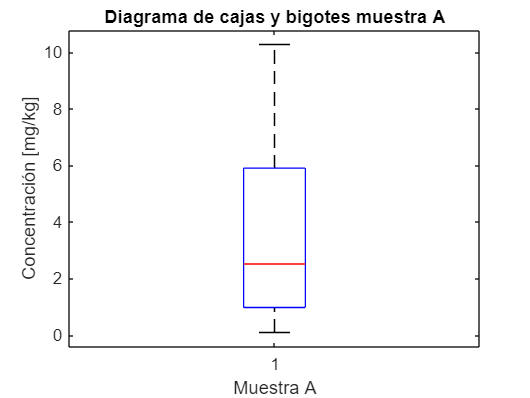

hold on
title('Diagrama de cajas y bigotes muestra A')
ylabel('Concentración [mg/kg]')
xlabel('Muestra A')
hold off


W_B = boxplot(B)

W_B =     0.0009
    1.0009
    2.0009
    3.0005
    4.0005
    5.0005
    6.0004


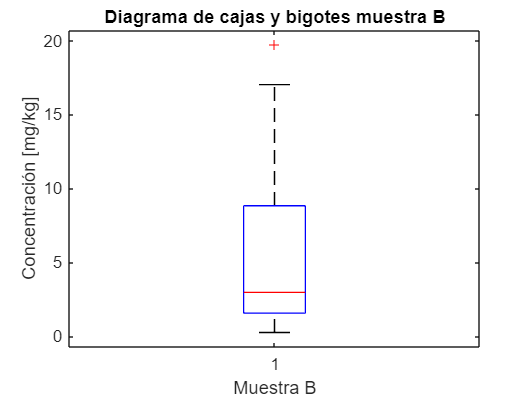

hold on
title('Diagrama de cajas y bigotes muestra B')
ylabel('Concentración [mg/kg]')
xlabel('Muestra B')
hold off

% Se observa que, para el diagrama en B, hay un valor atípico que es igual
% a 19.74 mg/kg.

% Punto 6
A

A =     1.7000
    6.2600
    7.5600
    7.9200
    0.9600
    2.4700
    2.5500
    0.2800
    1.3400
    0.7100


Cc_A = 5;
lim_A = zeros(1,length(A));
for i = 1:length(A)
    if A(i) >= Cc_A
        lim_A(i) = 1;
    else 
        lim_A(i) = 0;
    end
end
lim_A

lim_A =      0     1     1     1     0     0     0     0     0     0     0     0     1     0     0     0     1     0     1     0


Crit_A = sum(lim_A)

Crit_A = 6


A_area = 8000

A_area = 8000


A_area_limpiar = (Crit_A/length(A)) * A_area

A_area_limpiar = 2400


% De acuerdo con el resultado obtenido, se tiene que limpiar un área igual
% a 2400 m2 

% Punto 7
Cc_B = 10;
lim_B = zeros(1,length(B));
for i = 1:length(B)
    if B(i) >= Cc_B
        lim_B(i) = 1;
    else 
        lim_B(i) = 0;
    end
end
lim_B

lim_B =      0     1     1     1     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0


Crit_B = sum(lim_B)

Crit_B = 5


B_area = 8000

B_area = 8000


B_area_limpiar = (Crit_B/length(B)) * B_area

B_area_limpiar = 2000


% De acuerdo con el resultado obtenido, se tiene que limpiar un área igual
% a 2000 m2 

% Punto 8
Corr_AB = corrcoef(A_1, B_1)

Corr_AB =     1.0000    0.9804
    0.9804    1.0000


% El coeficiente de correlación es 0.6738

% Punto 9
Fraccion_A = ((length(A)-Crit_A)/length(A))*100

Fraccion_A = 70


Fraccion_B = ((length(B)-Crit_B)/length(B))*100

Fraccion_B = 75


% El 70% de los datos en A son menores a 5 mg/kg
% El 75% de los datos en B son menores a 10 mg/kg

% Punto 10 
% Respuesta en el punto 9

co =     0.5139    0.9804
    0.9804    1.9459


ans =     1.2906
   -2.3295
    1.9938
   -9.7286
    0.8609
  -20.2075
  -14.9042
  -58.5499
    0.5175
   17.0878


ans =   -47.0938
  -82.3671
 -109.6649
 -123.6996
 -134.6262
 -127.7513
 -117.0531
 -103.7317
  -90.8490
  -65.7108


ans =     1.0000    0.9804
    0.9804    1.0000
